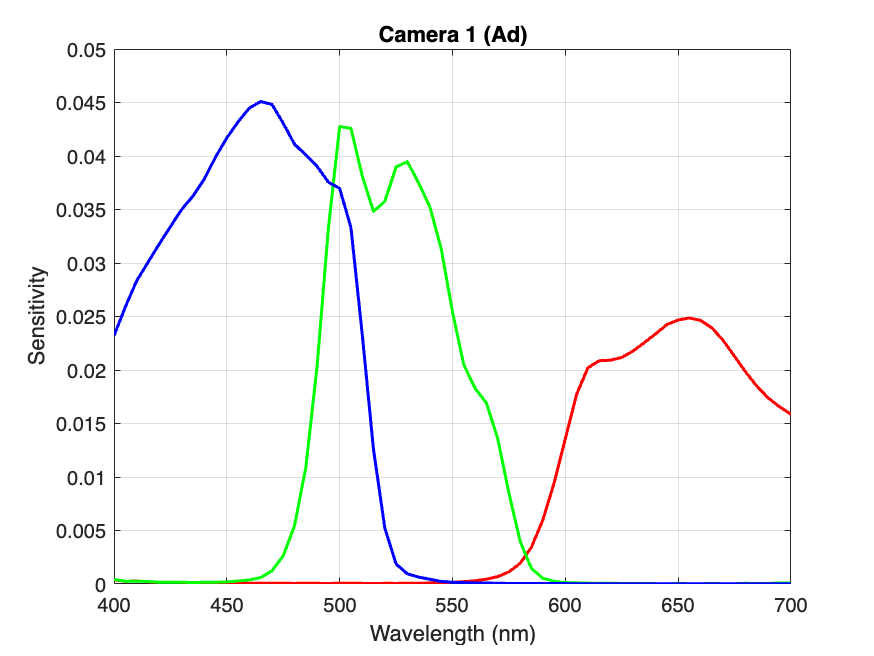

% Uppgift 1.1

load Ad.mat
load Ad2.mat

%skapar vår våglängdsvekotr
lambda = 400:5:700;

%Vi plottar tre kurvor samtidigt
plot(lambda, Ad(:,1), 'r', lambda, Ad(:,2), 'g', lambda, Ad(:,3), 'b', 'LineWidth', 1.5)
title('Camera 1 (Ad)')
xlabel('Wavelength (nm)')
ylabel('Sensitivity')
grid on

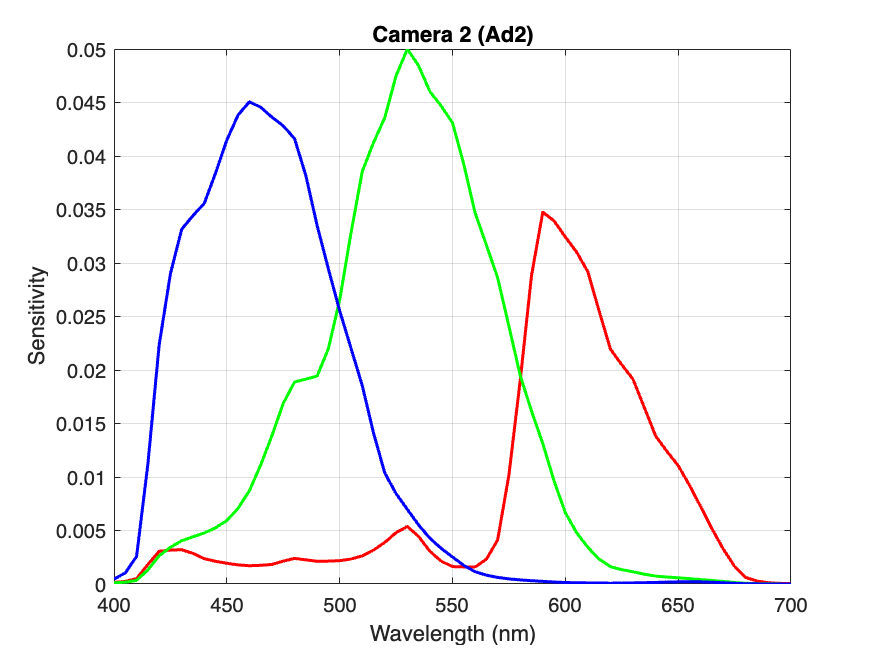


plot(lambda, Ad2(:,1), 'r', lambda, Ad2(:,2), 'g', lambda, Ad2(:,3), 'b', 'LineWidth', 1.5)
title('Camera 2 (Ad2)')
xlabel('Wavelength (nm)')
ylabel('Sensitivity')
grid on

% Uppgift 1.2

load chips20.mat
load illum.mat

%ekvation 7
RGB_raw_D65 = Ad'*(chips20(:,:).*CIED65)';
RGB2_raw_D65 = Ad2'*(chips20(:,:).*CIED65)';

disp('Camera 1 ,ad')

Camera 1 ,ad


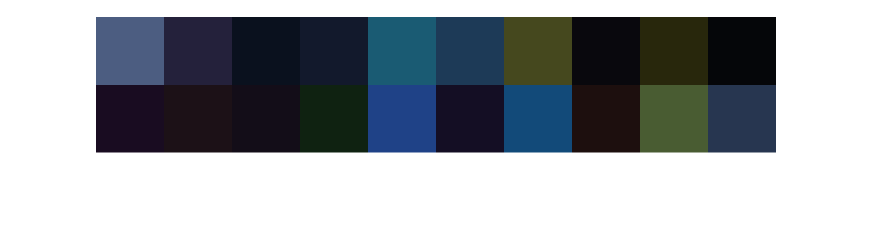

showRGB(RGB_raw_D65');


disp('Camera 2, ad2')

Camera 2, ad2


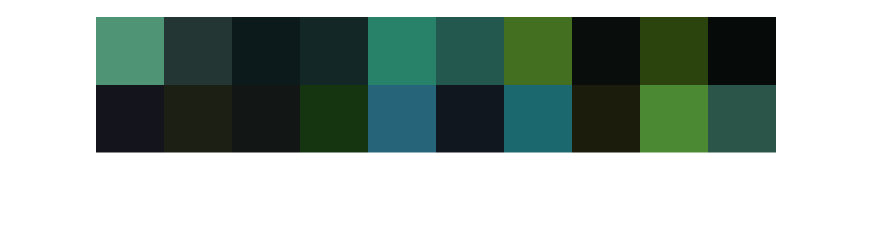

showRGB(RGB2_raw_D65');


% Spara för senare användning
%save RGB_raw_D65.mat RGB_raw_D65


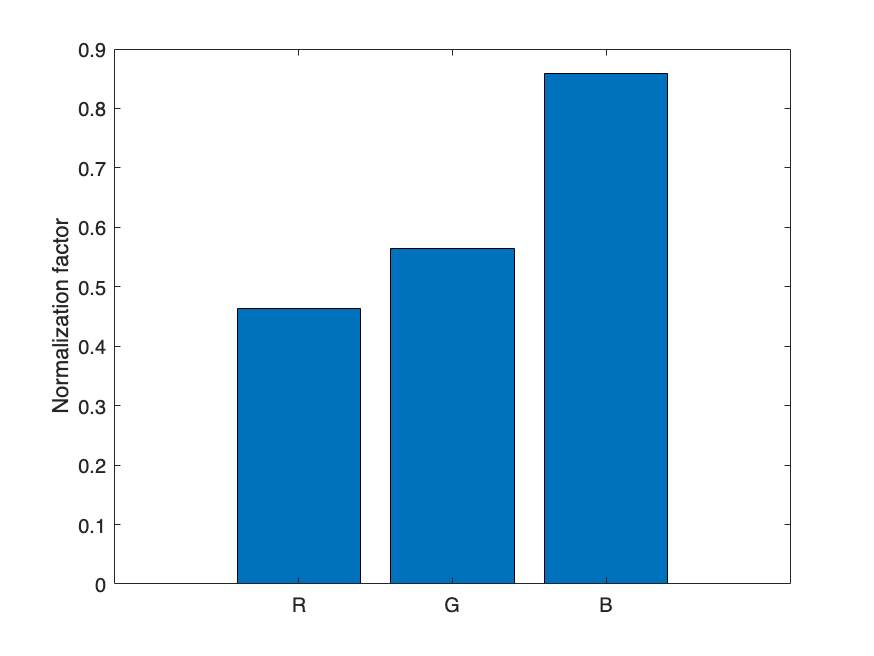

% Uppgift 2.1

% e blir en vektor med 1or
e = ones(1,61);

% vi normerar r g b 
normAd = Ad'*e';
normAd2 = Ad2'*e';

%visar realutat i stapel diagram

figure

bar(normAd)
xticklabels({'R','G','B'})
ylabel('Normalization factor')

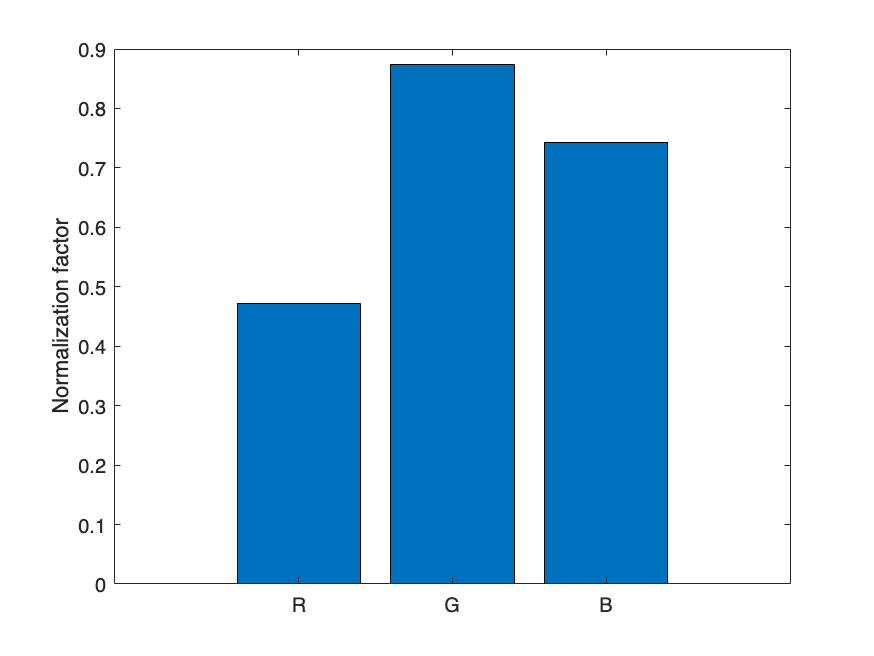


bar(normAd2)
xticklabels({'R','G','B'})
ylabel('Normalization factor')

% Uppgift 2.2

%kalibrera genom att dela rå RGB med normaliseringsfaktorer
RGB_cal_D65 = (Ad'*(chips20(:,:).*CIED65)')./normAd;

RGB2_cal_D65 = (Ad2'*(chips20(:,:).*CIED65)')./normAd2;

disp('Camera 1 ,ad')

Camera 1 ,ad


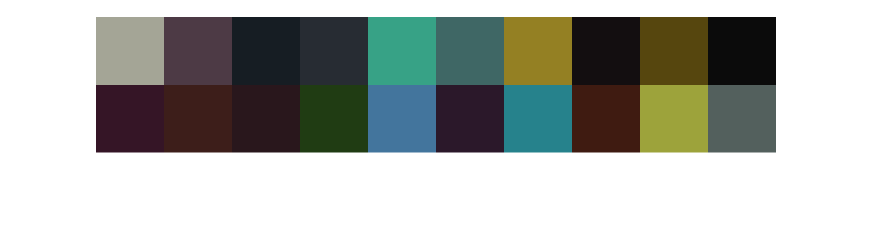

showRGB(RGB_cal_D65')


disp('Camera 2, ad2')

Camera 2, ad2


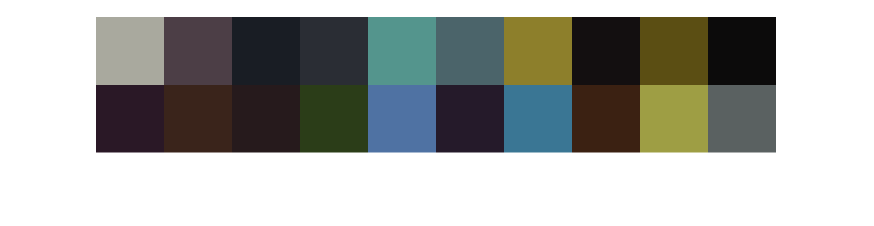

showRGB(RGB2_cal_D65')

% Uppgift 2.3

% plottar spectrial power and våglängd
disp('Daylight')

Daylight


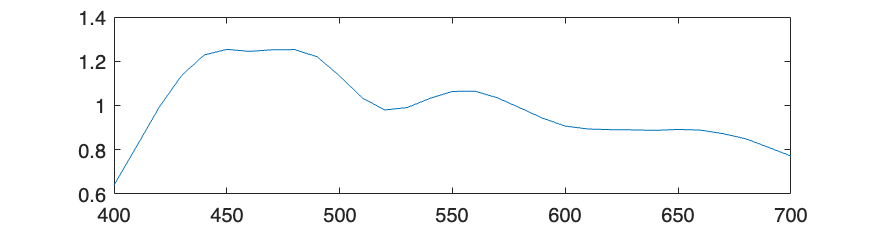


plot(lambda, CIED65)


disp('Indoor')

Indoor


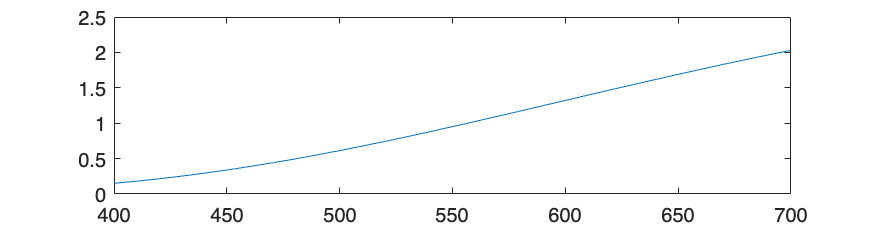


plot(lambda, CIEA)

% Uppgift 2.4

%beräknar kalibrerad RGB
RGB_CIED652 = (Ad'*(chips20(:,:).*CIED65)')./normAd;

RGB_CIEA = (Ad'*(chips20(:,:).*CIEA)')./normAd;

disp('Daylight')

Daylight


showRGB(RGB_CIED652');


disp('Indoor')

Indoor


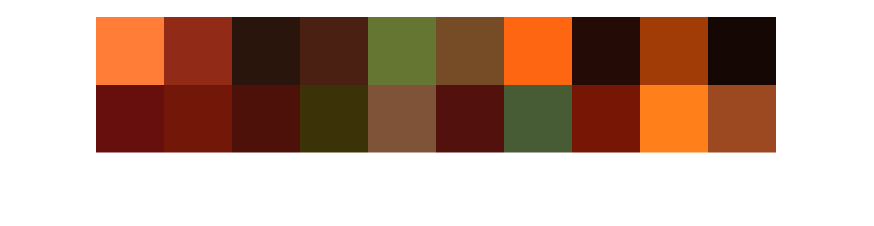

showRGB(RGB_CIEA');

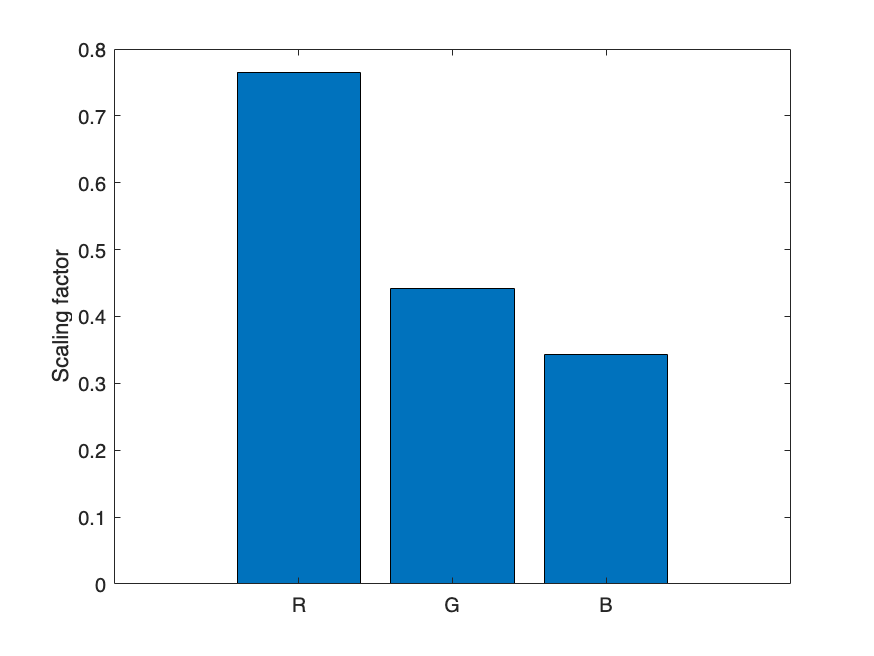

% Uppgift 2.5 

R = ones(1,61);

%Räknar ut normaliseringsfaktorn
%anväder eq 8
normCIEA = Ad'*(R.*CIEA)';
normCIED65 = Ad'*(R.*CIED65)';

figure

bar(normCIEA)
xticklabels({'R','G','B'})
ylabel('Scaling factor')

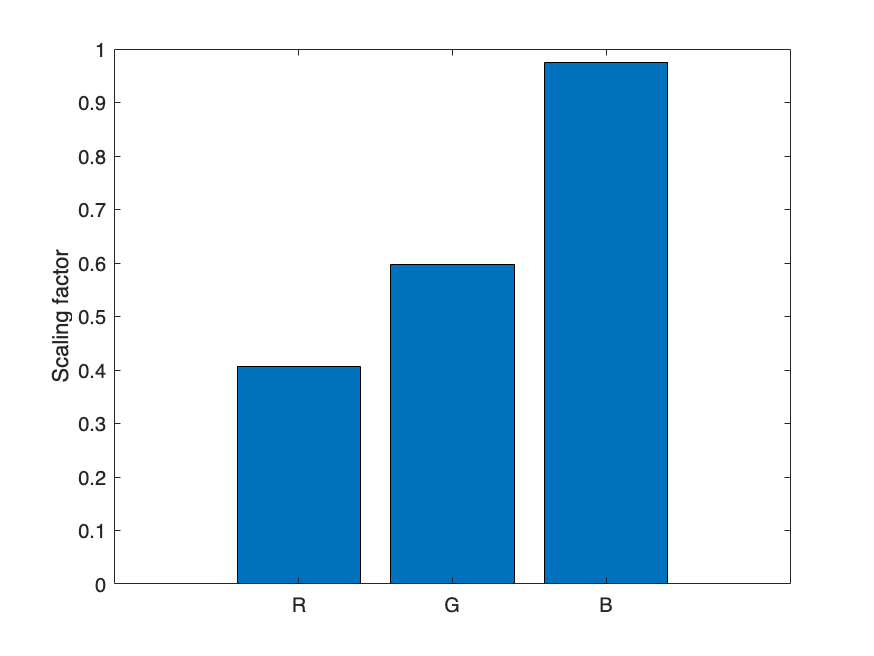


bar(normCIED65)
xticklabels({'R','G','B'})
ylabel('Scaling factor')

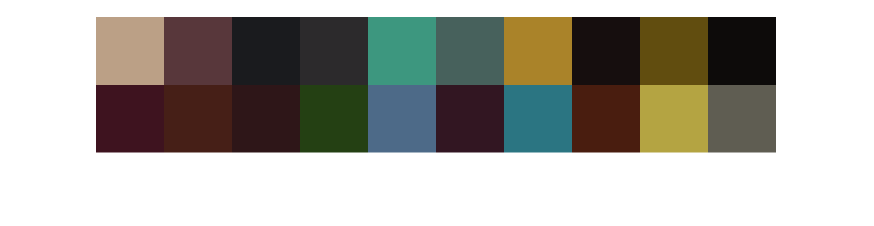


% Salar med normaliseringsfaktorn 
RGB_cal_A = (Ad'*(chips20(:,:).*CIEA)')./normCIEA;
RGB_cal_D652 = (Ad'*(chips20(:,:).*CIED65)')./normCIED65;


showRGB(RGB_cal_A');

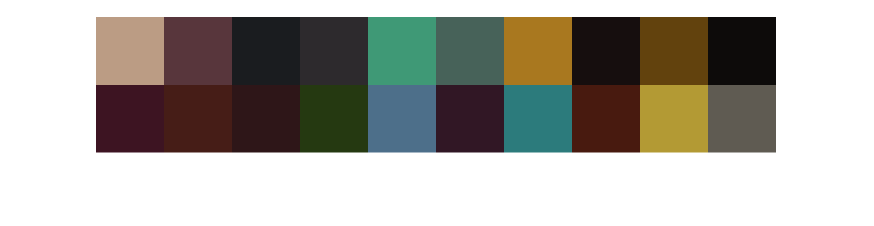


showRGB(RGB_cal_D652');

% Uppgift 3.1

load xyz.mat

%Normalization factor
k = 100./(CIED65*xyz(:,2));

%XYZ-values 
XYZ_D65_ref = xyz'*( chips20(:,:).*CIED65)' .* k;


% Uppgift 3.2

load M_XYZ2RGB.mat

% RGB -> XYZ (estimated) med inversen av RGB matrisen
MXYZ_est = inv(M_XYZ2RGB) * RGB_cal_D65;   % 3 x 20

%Estimation värden i CIELAB
[L, a, b] =  xyz2lab(MXYZ_est(1,:)', MXYZ_est(2,:)', MXYZ_est(3,:)');

E_LAB = zeros(3,20);
E_LAB(1,:) = L;
E_LAB(2,:) = a;
E_LAB(3,:) = b;

%Reference
[L, a, b] =  xyz2lab(XYZ_D65_ref(1,:)', XYZ_D65_ref(2,:)', XYZ_D65_ref(3,:)');

REF_LAB = zeros(3,20);
REF_LAB(1,:) = L;
REF_LAB(2,:) = a;
REF_LAB(3,:) = b;
    
%Color difference, Compute Delta E_ab (euclidian distance) 
dE = sqrt((E_LAB(1,:)-REF_LAB(1,:)).^2+(E_LAB(2,:)-REF_LAB(2,:)).^2+(E_LAB(3,:)-REF_LAB(3,:)).^2);

% Mean and maximum Delta E
dE_Mean = mean(dE)

dE_Mean = 12.6418

dE_Max  = max(dE)

dE_Max = 31.6232

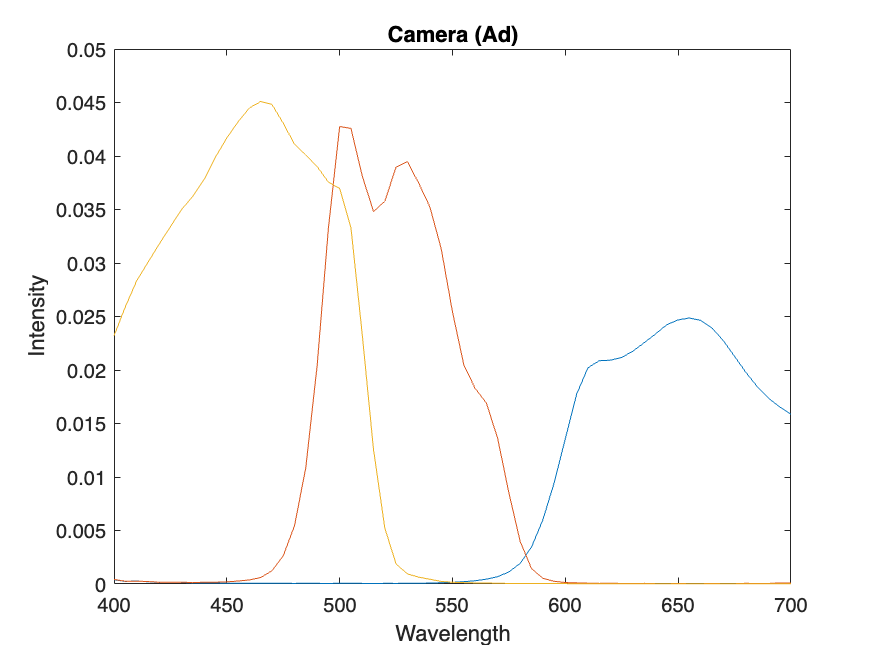

% Uppgift 3.3


x = 400:5:700;

figure

%Camera
plot(x,Ad);
xlabel('Wavelength');  
ylabel('Intensity'); 
title('Camera (Ad)');

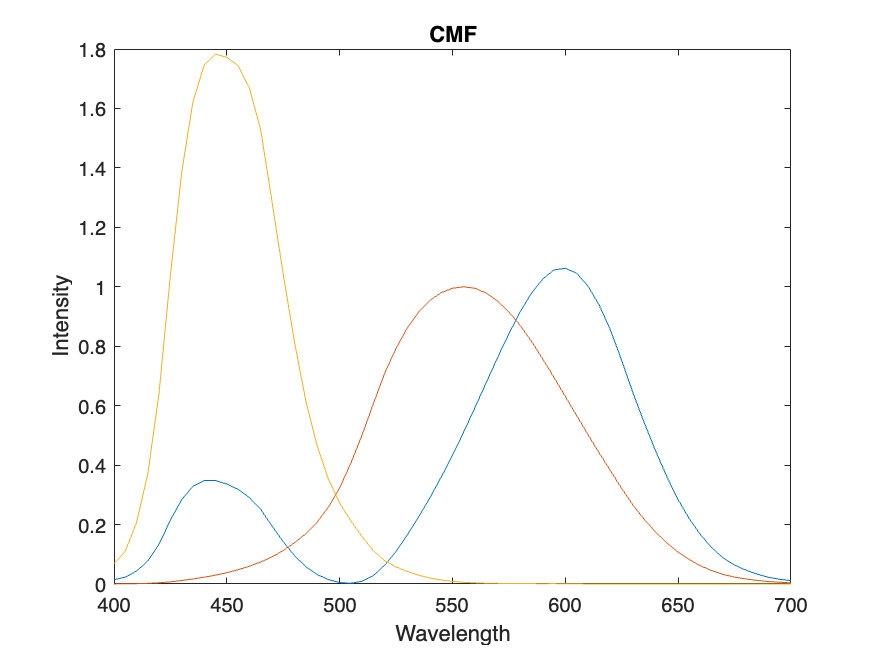


% CMF of standard observer 
plot(x,xyz);
xlabel('Wavelength');  
ylabel('Intensity'); 
title('CMF');


% Luther ives condition säger att funkterna se likadana ut för att
% se samma färg.


% Uppgift 3.4

%Räknar med hjälp av linear regression
%Conversion matris mellan RGB och XYZ 
A = pinv(RGB_cal_D65') * XYZ_D65_ref';

%Estimation matris from conversion
estimate = RGB_cal_D65'*A; %D*A

%Estimation values in CIELAB
[L, a, b] =  xyz2lab(estimate(:,1)', estimate(:,2)', estimate(:,3)');

E_LAB = zeros(3,20);
E_LAB(1,:) = L;
E_LAB(2,:) = a;
E_LAB(3,:) = b;

%Reference
[L, a, b] =  xyz2lab(XYZ_D65_ref(1,:)', XYZ_D65_ref(2,:)', XYZ_D65_ref(3,:)');

REF_LAB = zeros(3,20);
REF_LAB(1,:) = L;
REF_LAB(2,:) = a;
REF_LAB(3,:) = b;
    
%Color difference ΔE_ab
dE = sqrt((E_LAB(1,:) - REF_LAB(1,:)).^2 + (E_LAB(2,:) - REF_LAB(2,:)).^2 + (E_LAB(3,:) - REF_LAB(3,:)).^2);

dE_Mean = mean(dE)

dE_Mean = 2.1977

dE_Max  = max(dE)

dE_Max = 5.8376

% Uppgift 3.5

% Räknar ut polynomial regression matrisen
A = Optimize_poly(RGB_cal_D65, XYZ_D65_ref);

XYZ_est_poly = Polynomial_regression(RGB_cal_D65, A);
% nu är den dock 3x20
XYZ_est_poly = XYZ_est_poly';  % nu är den isälle 20x3


% Estimerade värden in CIELAB
[L, a, b] = xyz2lab(XYZ_est_poly(:,1), XYZ_est_poly(:,2), XYZ_est_poly(:,3));

E_LAB = zeros(3,20);
E_LAB(1,:) = L';
E_LAB(2,:) = a';
E_LAB(3,:) = b';


% Ref värderna i CIELAB
[L, a, b] = xyz2lab(XYZ_D65_ref(1,:)', XYZ_D65_ref(2,:)', XYZ_D65_ref(3,:)');

REF_LAB = zeros(3,20);
REF_LAB(1,:) = L;
REF_LAB(2,:) = a;
REF_LAB(3,:) = b;


% --- Color difference ΔE_ab ---
e = sqrt((E_LAB(1,:) - REF_LAB(1,:)).^2 + (E_LAB(2,:) - REF_LAB(2,:)).^2 + (E_LAB(3,:) - REF_LAB(3,:)).^2);

dE_Mean3 = mean(e)

dE_Mean3 = 1.0238

dE_Max3  = max(e)

dE_Max3 = 3.1053


save('XYZ_est_poly.mat', 'XYZ_est_poly');


